clc
clear all
close all
loadData_gr
SIDnum = unique(grdata.SubjectID);
grdata.Trial = categorical(grdata.Trial);
grdata.SubjectID = categorical(grdata.SubjectID);
grdata.Texture = categorical(grdata.Texture);
toDelete = grdata.Trial == 'Trial 1';
grdata(toDelete,:) = [];
grdata.log_PLFR = log(grdata.PLFR);
grdata.log_PGFR = log(grdata.PGFR);
grdata.Weightcentered = grdata.Weight - mean(unique(grdata.Weight));
SID = unique(grdata.SubjectID);
Weight = unique(grdata.Weight);

## PLFR vs. Weight (Linear model)

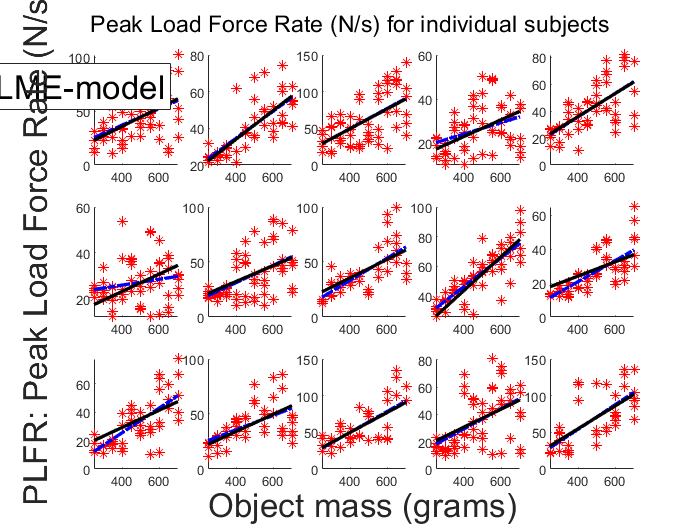

plfr_weight_ols = fitlm(grdata,'PLFR ~ Weightcentered');
plfr_lme1 = fitlme(grdata(grdata.Texture == 'C1',:),'PLFR ~ 1 + Weightcentered');
plfr_lme2 = fitlme(grdata(grdata.Texture == 'C1',:),'PLFR ~ 1 + Weightcentered + (1|SubjectID)');
plfr_lme3 = fitlme(grdata(grdata.Texture == 'C1',:),'PLFR ~ 1 + Weightcentered + (1 + Weightcentered|SubjectID)');
fe = fixedEffects(plfr_lme3);
[~,~,re] = randomEffects(plfr_lme3);
re.Level = nominal(re.Level);
re.Name = nominal(re.Name);
plfr_lme4 = fitlme(grdata(grdata.Texture == 'C1',:),'PLFR ~ 1 + Weightcentered + (1 + Weightcentered|SubjectID)+ (1|Trial)');
            comp_plfr = compare(plfr_lme1,plfr_lme2,'nsim',100);
            comp_plfr1 = compare(plfr_lme2,plfr_lme3,'nsim',100);
            comp_plfr2 = compare(plfr_lme3,plfr_lme4,'nsim',100);
plfr_lm_1 = fitlm(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).PLFR);
plfr_lm_2 = fitlm(grdata(grdata.SubjectID==SID(2)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(2)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_3 = fitlm(grdata(grdata.SubjectID==SID(3)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(3)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_4 = fitlm(grdata(grdata.SubjectID==SID(4)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(4)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_5 = fitlm(grdata(grdata.SubjectID==SID(5)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(5)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_6 = fitlm(grdata(grdata.SubjectID==SID(6)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(6)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_7 = fitlm(grdata(grdata.SubjectID==SID(7)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(7)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_8 = fitlm(grdata(grdata.SubjectID==SID(8)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(8)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_9 = fitlm(grdata(grdata.SubjectID==SID(9)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(9)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_10 = fitlm(grdata(grdata.SubjectID==SID(10)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(10)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_11 = fitlm(grdata(grdata.SubjectID==SID(11)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(11)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_12 = fitlm(grdata(grdata.SubjectID==SID(12)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(12)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_13 = fitlm(grdata(grdata.SubjectID==SID(13)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(13)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_14 = fitlm(grdata(grdata.SubjectID==SID(14)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(14)  & grdata.Texture == 'C1',:).PLFR);
plfr_lm_15 = fitlm(grdata(grdata.SubjectID==SID(15)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(15)  & grdata.Texture == 'C1',:).PLFR);

f1 = figure(1);
hold on
sgtitle('Peak Load Force Rate (N/s) for individual subjects')

subplot(3,5,1)
hold on
A = scatter(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).PLFR,'*r','DisplayName','PLFR');
B = plot(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,plfr_lm_1.Coefficients.Estimate(1)+plfr_lm_1.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2,'DisplayName','OLS-model');
C = plot(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(1))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(1))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2,'DisplayName','LME-model');
hold off

subplot(3,5,2)
hold on
scatter(grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,plfr_lm_2.Coefficients.Estimate(1)+plfr_lm_2.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(2))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(2))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,3)
hold on
scatter(grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,plfr_lm_3.Coefficients.Estimate(1)+plfr_lm_3.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(3))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(3))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,4)
hold on
scatter(grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,plfr_lm_4.Coefficients.Estimate(1)+plfr_lm_4.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(4))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(4))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,5)
hold on
scatter(grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,plfr_lm_5.Coefficients.Estimate(1)+plfr_lm_5.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(5))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(5))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,6)
hold on
scatter(grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,plfr_lm_6.Coefficients.Estimate(1)+plfr_lm_6.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(6))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(6))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,7)
hold on
scatter(grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,plfr_lm_7.Coefficients.Estimate(1)+plfr_lm_7.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(7))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(7))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,8)
hold on
scatter(grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,plfr_lm_8.Coefficients.Estimate(1)+plfr_lm_8.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(8))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(8))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,9)
hold on
scatter(grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,plfr_lm_9.Coefficients.Estimate(1)+plfr_lm_9.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(9))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(9))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,10)
hold on
scatter(grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,plfr_lm_10.Coefficients.Estimate(1)+plfr_lm_10.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(10))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(10))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,11)
hold on
scatter(grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,plfr_lm_11.Coefficients.Estimate(1)+plfr_lm_11.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(11))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(11))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,12)
hold on
scatter(grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,plfr_lm_12.Coefficients.Estimate(1)+plfr_lm_12.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(2))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(12))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,13)
hold on
scatter(grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,plfr_lm_13.Coefficients.Estimate(1)+plfr_lm_13.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(13))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(13))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,14)
hold on
scatter(grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,plfr_lm_14.Coefficients.Estimate(1)+plfr_lm_14.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(14))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(14))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

subplot(3,5,15)
hold on
scatter(grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,plfr_lm_15.Coefficients.Estimate(1)+plfr_lm_15.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,fe(1)+re.Estimate(re.Level == num2str(SIDnum(15))&re.Name == '(Intercept)')+(fe(2)+re.Estimate(re.Level == num2str(SIDnum(15))&re.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weightcentered,'-k','LineWidth',2)
hold off

han = axes(f1,'visible','off');
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';
xlabel(han,'Object mass (grams)','FontSize',20);
ylabel(han,'PLFR: Peak Load Force Rate (N/s)','FontSize',20);
lgd2 = legend([A,B,C],'FontSize',20);
% set(lgd2,'MarkerSize',20);
lgd2.Orientation = 'horizontal';

## PLFR vs. Weight (log-linear)

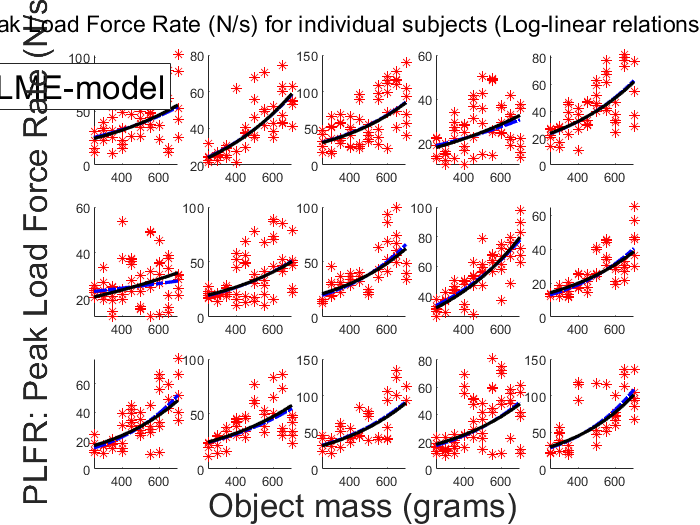

lplfr_weight_ols = fitlm(grdata,'log_PLFR ~ Weightcentered');
lplfr_lme1 = fitlme(grdata(grdata.Texture == 'C1',:),'log_PLFR ~ 1 + Weightcentered');
lplfr_lme2 = fitlme(grdata(grdata.Texture == 'C1',:),'log_PLFR ~ 1 + Weightcentered + (1|SubjectID)');
lplfr_lme3 = fitlme(grdata(grdata.Texture == 'C1',:),'log_PLFR ~ 1 + Weightcentered + (1 + Weightcentered|SubjectID)');
lfe = fixedEffects(lplfr_lme3);
[~,~,lre] = randomEffects(lplfr_lme3);
lre.Level = nominal(lre.Level);
lre.Name = nominal(lre.Name);
lplfr_lme4 = fitlme(grdata(grdata.Texture == 'C1',:),'log_PLFR ~ 1 + Weightcentered + (1 + Weightcentered|SubjectID)+ (1|Trial)');
            comp_plfr = compare(lplfr_lme1,lplfr_lme2,'nsim',100);
            comp_plfr1 = compare(lplfr_lme2,lplfr_lme3,'nsim',100);
            comp_plfr2 = compare(lplfr_lme3,lplfr_lme4,'nsim',100);
lplfr_lm_1 = fitlm(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_2 = fitlm(grdata(grdata.SubjectID==SID(2)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(2)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_3 = fitlm(grdata(grdata.SubjectID==SID(3)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(3)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_4 = fitlm(grdata(grdata.SubjectID==SID(4)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(4)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_5 = fitlm(grdata(grdata.SubjectID==SID(5)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(5)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_6 = fitlm(grdata(grdata.SubjectID==SID(6)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(6)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_7 = fitlm(grdata(grdata.SubjectID==SID(7)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(7)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_8 = fitlm(grdata(grdata.SubjectID==SID(8)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(8)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_9 = fitlm(grdata(grdata.SubjectID==SID(9)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(9)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_10 = fitlm(grdata(grdata.SubjectID==SID(10)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(10)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_11 = fitlm(grdata(grdata.SubjectID==SID(11)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(11)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_12 = fitlm(grdata(grdata.SubjectID==SID(12)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(12)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_13 = fitlm(grdata(grdata.SubjectID==SID(13)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(13)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_14 = fitlm(grdata(grdata.SubjectID==SID(14)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(14)  & grdata.Texture == 'C1',:).log_PLFR);
lplfr_lm_15 = fitlm(grdata(grdata.SubjectID==SID(15)  & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(15)  & grdata.Texture == 'C1',:).log_PLFR);

f1 = figure(2);
hold on
sgtitle('Peak Load Force Rate (N/s) for individual subjects (Log-linear relationship')

subplot(3,5,1)
hold on
A = scatter(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).PLFR,'*r','DisplayName','PLFR');
B = plot(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_1.Coefficients.Estimate(1)+lplfr_lm_1.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2,'DisplayName','OLS-model');
C = plot(grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(1))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(1))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(1) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2,'DisplayName','LME-model');
hold off

subplot(3,5,2)
hold on
scatter(grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_2.Coefficients.Estimate(1)+lplfr_lm_2.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(2))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(2))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(2) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,3)
hold on
scatter(grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_3.Coefficients.Estimate(1)+lplfr_lm_3.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(3))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(3))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(3) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,4)
hold on
scatter(grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_4.Coefficients.Estimate(1)+lplfr_lm_4.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(4))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(4))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(4) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,5)
hold on
scatter(grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_5.Coefficients.Estimate(1)+lplfr_lm_5.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(5))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(5))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(5) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,6)
hold on
scatter(grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_6.Coefficients.Estimate(1)+lplfr_lm_6.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(6))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(6))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(6) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,7)
hold on
scatter(grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_7.Coefficients.Estimate(1)+lplfr_lm_7.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(7))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(7))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(7) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,8)
hold on
scatter(grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_8.Coefficients.Estimate(1)+lplfr_lm_8.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(8))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(8))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(8) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,9)
hold on
scatter(grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_9.Coefficients.Estimate(1)+lplfr_lm_9.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(9))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(9))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(9) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,10)
hold on
scatter(grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_10.Coefficients.Estimate(1)+lplfr_lm_10.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(10))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(10))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(10) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,11)
hold on
scatter(grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_11.Coefficients.Estimate(1)+lplfr_lm_11.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(11))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(11))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(11) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,12)
hold on
scatter(grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_12.Coefficients.Estimate(1)+lplfr_lm_12.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(2))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(12))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(12) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,13)
hold on
scatter(grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_13.Coefficients.Estimate(1)+lplfr_lm_13.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(13))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(13))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(13) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,14)
hold on
scatter(grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_14.Coefficients.Estimate(1)+lplfr_lm_14.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(14))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(14))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(14) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

subplot(3,5,15)
hold on
scatter(grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).PLFR,'*r')
plot(grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,exp(lplfr_lm_15.Coefficients.Estimate(1)+lplfr_lm_15.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight),'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weight,exp(lfe(1)+lre.Estimate(lre.Level == num2str(SIDnum(15))&lre.Name == '(Intercept)')+(lfe(2)+lre.Estimate(lre.Level == num2str(SIDnum(15))&lre.Name == 'Weightcentered'))*grdata(grdata.SubjectID==SID(15) & grdata.Texture == 'C1',:).Weightcentered),'-k','LineWidth',2)
hold off

han = axes(f1,'visible','off');
han.XLabel.Visible = 'on';
han.YLabel.Visible = 'on';
xlabel(han,'Object mass (grams)','FontSize',20);
ylabel(han,'PLFR: Peak Load Force Rate (N/s)','FontSize',20);
lgd2 = legend([A,B,C],'FontSize',20);
% set(lgd2,'MarkerSize',20);
lgd2.Orientation = 'horizontal';

## PGFR vs. Texture (Log model)

A1 = 0.94; A2 = 1; B1 = 0.5; B2 = 0.59; C1 = 1.17;

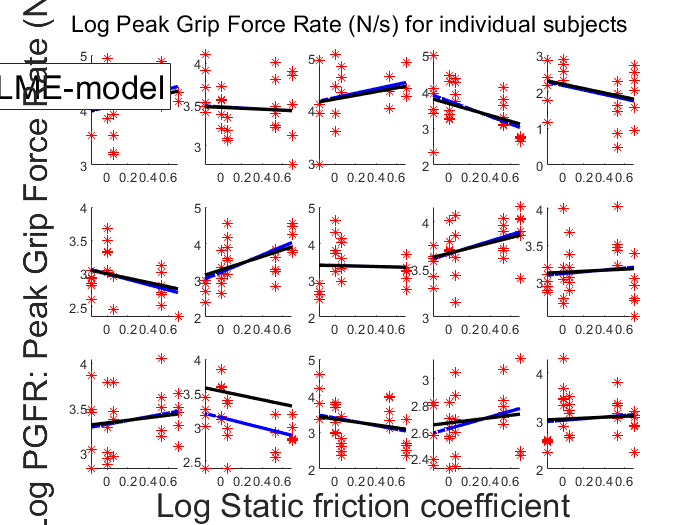

grdata.sfc = zeros(height(grdata),1);
grdata.sfc_inverse = zeros(height(grdata),1);
for i = 1:height(grdata)
   if grdata.Texture(i) == 'A1'
       grdata.sfc(i)=0.94;
       grdata.sfc_inverse(i) = 1/0.94;
   end
   if grdata.Texture(i) == 'A2'
       grdata.sfc(i)=1;
       grdata.sfc_inverse(i) = 1;
   end
   if grdata.Texture(i) == 'B1'
       grdata.sfc(i)=0.5;
       grdata.sfc_inverse(i) = 2;
   end
   if grdata.Texture(i) == 'B2'
       grdata.sfc(i)=0.59;
       grdata.sfc_inverse(i) = 1/0.59;
   end
   if grdata.Texture(i) == 'C1'
       grdata.sfc(i)=1.17;
       grdata.sfc_inverse(i) = 1/1.17;
   end
   
end
grdata.log_sfc = log(grdata.sfc_inverse);
grdata.sfc_centered = grdata.log_sfc-mean(unique(grdata.log_sfc));
% pgfr_Texture_ols = fitlm(grdata(grdata.Weight == 250,:),'PGFR ~ sfc');
pgfr_lme1 = fitlme(grdata(grdata.Weight == 250,:),'log_PGFR ~ sfc_centered');
pgfr_lme2 = fitlme(grdata(grdata.Weight == 250,:),'log_PGFR ~ sfc_centered + (1|SubjectID)');
pgfr_lme3 = fitlme(grdata(grdata.Weight == 250,:),'log_PGFR ~ sfc_centered + (1+sfc_centered|SubjectID)');
fe1 = fixedEffects(pgfr_lme3);
[~,~,re1] = randomEffects(pgfr_lme3);
re1.Level = nominal(re1.Level);
re1.Name = nominal(re1.Name);
pgfr_lme4 = fitlme(grdata(grdata.Weight == 250,:),'log_PGFR ~ sfc_centered + (1+sfc_centered|SubjectID) + (1|Trial)');
                comp_pgfr = compare(plfr_lme1,plfr_lme2,'nsim',100);
                comp_pgfr1 = compare(pgfr_lme2,pgfr_lme3,'nsim',100);
                comp_pgfr2 = compare(pgfr_lme3,pgfr_lme4,'nsim',100);

pgfr_lm_1 = fitlm(grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_2 = fitlm(grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_3 = fitlm(grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_4 = fitlm(grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_5 = fitlm(grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_6 = fitlm(grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_7 = fitlm(grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_8 = fitlm(grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_9 = fitlm(grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_10 = fitlm(grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_11 = fitlm(grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_12 = fitlm(grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_13 = fitlm(grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_14 = fitlm(grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_PGFR);
pgfr_lm_15 = fitlm(grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_PGFR);

f2 = figure(3);
hold on
sgtitle('Log Peak Grip Force Rate (N/s) for individual subjects')

subplot(3,5,1)
hold on
A1 = scatter(grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_PGFR,'*r','DisplayName','PGFR');
B1 = plot(grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_sfc,pgfr_lm_1.Coefficients.Estimate(1)+pgfr_lm_1.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2,'DisplayName','OLS-model');
C1 = plot(grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(1))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(1))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(1) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2,'DisplayName','LME-model');
hold off

subplot(3,5,2)
hold on
scatter(grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_sfc,pgfr_lm_2.Coefficients.Estimate(1)+pgfr_lm_2.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(2))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(2))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(2) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,3)
hold on
scatter(grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_sfc,pgfr_lm_3.Coefficients.Estimate(1)+pgfr_lm_3.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(3))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(3))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(3) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,4)
hold on
scatter(grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_sfc,pgfr_lm_4.Coefficients.Estimate(1)+pgfr_lm_4.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(4))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(4))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(4) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,5)
hold on
scatter(grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_sfc,pgfr_lm_5.Coefficients.Estimate(1)+pgfr_lm_5.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(5))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(5))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(5) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,6)
hold on
scatter(grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_sfc,pgfr_lm_6.Coefficients.Estimate(1)+pgfr_lm_6.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(6))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(6))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(6) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,7)
hold on
scatter(grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_sfc,pgfr_lm_7.Coefficients.Estimate(1)+pgfr_lm_7.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(7))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(7))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(7) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,8)
hold on
scatter(grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_sfc,pgfr_lm_8.Coefficients.Estimate(1)+pgfr_lm_8.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(8))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(8))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(8) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,9)
hold on
scatter(grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_sfc,pgfr_lm_9.Coefficients.Estimate(1)+pgfr_lm_9.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(9))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(9))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(9) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,10)
hold on
scatter(grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_sfc,pgfr_lm_10.Coefficients.Estimate(1)+pgfr_lm_10.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(10))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(10))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(10) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,11)
hold on
scatter(grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_sfc,pgfr_lm_11.Coefficients.Estimate(1)+pgfr_lm_11.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(11))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(11))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(11) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,12)
hold on
scatter(grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_sfc,pgfr_lm_12.Coefficients.Estimate(1)+pgfr_lm_12.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(2))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(12))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(12) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,13)
hold on
scatter(grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_sfc,pgfr_lm_13.Coefficients.Estimate(1)+pgfr_lm_13.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(13))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(13))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(13) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,14)
hold on
scatter(grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_sfc,pgfr_lm_14.Coefficients.Estimate(1)+pgfr_lm_14.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(14))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(14))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(14) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

subplot(3,5,15)
hold on
scatter(grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_sfc,grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_PGFR,'*r')
plot(grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_sfc,pgfr_lm_15.Coefficients.Estimate(1)+pgfr_lm_15.Coefficients.Estimate(2)*grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_sfc,'-.b','LineWidth',2)
plot(grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).log_sfc,fe1(1)+re1.Estimate(re1.Level == num2str(SIDnum(15))&re1.Name == '(Intercept)')+(fe1(2)+re1.Estimate(re1.Level == num2str(SIDnum(15))&re1.Name == 'sfc_centered'))*grdata(grdata.SubjectID==SID(15) & grdata.Weight == 250,:).sfc_centered,'-k','LineWidth',2)
hold off

han1 = axes(f2,'visible','off');
han1.XLabel.Visible = 'on';
han1.YLabel.Visible = 'on';
xlabel(han1,'Log Static friction coefficient','FontSize',20);
ylabel(han1,'Log PGFR: Peak Grip Force Rate (N/s)','FontSize',20);
lgd3 = legend([A1,B1,C1],'FontSize',20);
% set(lgd2,'MarkerSize',20);
lgd3.Orientation = 'horizontal';

## Mixed effects of weight and texture on PLFR (power model)

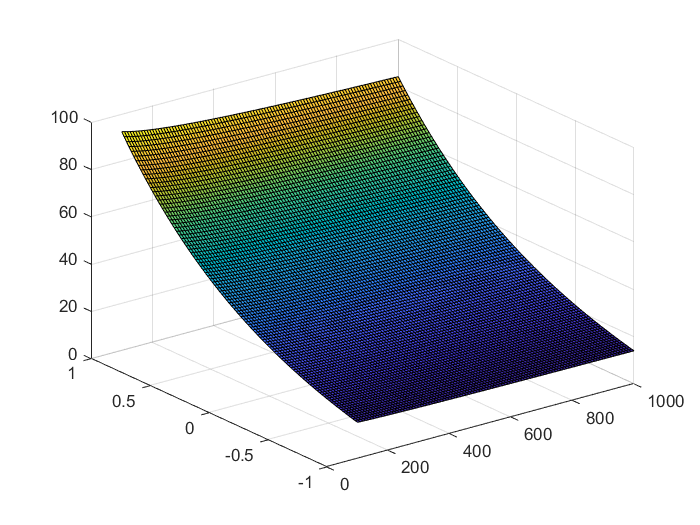

%PLFR = alpha \times W^(Beta) \times T^(Gamma)
%log(PLFR) = log(alpha) + Beta log(W) + Gamma log(T)

grdata.logweight = log(grdata.Weight);
grdata.logweightcentered = grdata.logweight - mean(unique(grdata.logweight));
lplfr_lme11 = fitlme(grdata,'log_PLFR ~ logweightcentered + sfc_centered');
lplfr_lme21 = fitlme(grdata,'log_PLFR ~ logweightcentered + sfc_centered + (1|SubjectID)');
compare_complete = compare(lplfr_lme1,lplfr_lme2);
fe3 = fixedEffects(lplfr_lme1);
compare_complete1 = compare(lplfr_lme11,lplfr_lme21);
fe4 = fixedEffects(lplfr_lme21);
pweight = linspace(100,1000,100);
pweightcentered = log(pweight)-mean(log(pweight));
ptexture = linspace(-1,1,100);
ptexturecentered = ptexture - mean(ptexture);
[Wtp,Ttp] = meshgrid(pweightcentered,ptexturecentered);
Zt = exp(fe4(1) + fe4(2)*Wtp + fe4(3)*Ttp);
figure(4)
surf(pweight,ptexture,Zt);

## Mixed effects of weight and texture on PGFR (power model)

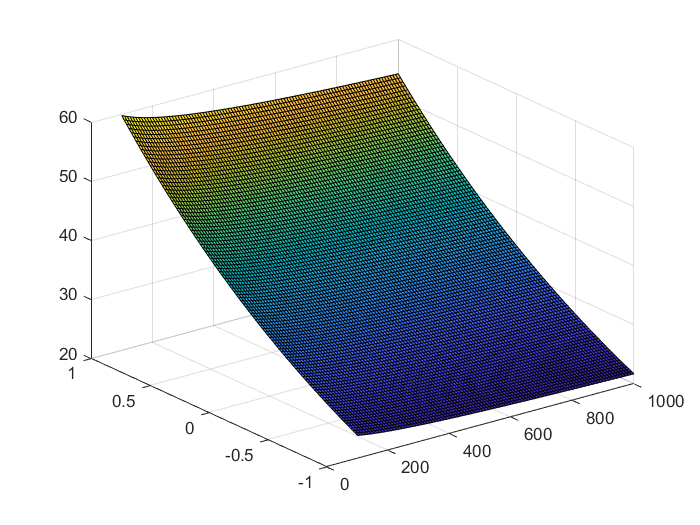

%PGFR = alpha \times W^(Beta) \times T^(Gamma)
%log(PGFR) = log(alpha) + Beta log(W) + Gamma log(T)

lpgfr_lme1 = fitlme(grdata,'log_PGFR ~ logweightcentered + sfc_centered');
lpgfr_lme2 = fitlme(grdata,'log_PGFR ~ logweightcentered + sfc_centered + (1|SubjectID)');
compare_complete1 = compare(lpgfr_lme1,lpgfr_lme2);
fe5 = fixedEffects(lpgfr_lme1);
Zt = exp(fe5(1) + fe5(2)*Wtp + fe5(3)*Ttp);

figure(5)
surf(pweight,ptexture,Zt);

## Mixed effects of weight and texture on PLFR (power model-2)

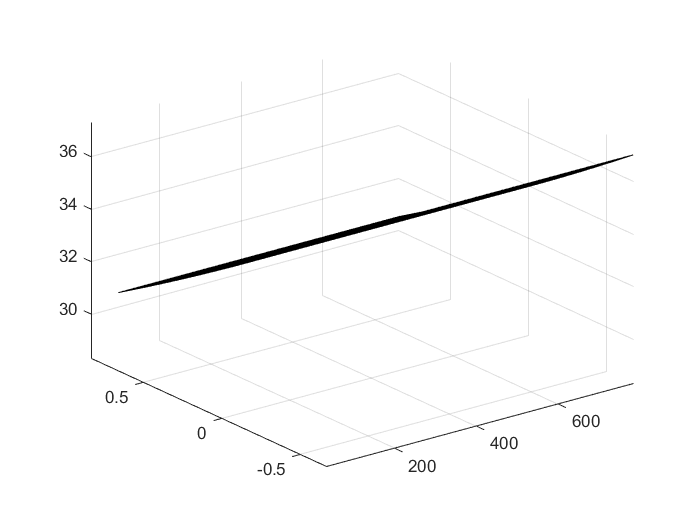

%PLFR = alpha \times e^W \times T^(Gamma)
%log(PLFR) = log(alpha) + W + Gamma log(T)
lplfr_lme12 = fitlme(grdata,'log_PLFR ~ Weightcentered + sfc_centered');
lplfr_lme22 = fitlme(grdata,'log_PLFR ~ Weightcentered + sfc_centered + (1|SubjectID)');
compare_complete2 = compare(lplfr_lme12,lplfr_lme22);
fe6 = fixedEffects(lplfr_lme12);
compare_complete12 = compare(lplfr_lme12,lplfr_lme22);
fe7 = fixedEffects(lplfr_lme22);
pweight = linspace(100,1000,100);
pweightcentered = log(pweight)-mean(log(pweight));
ptexture = linspace(-1,1,100);
ptexturecentered = ptexture - mean(ptexture);
[Wtp,Ttp] = meshgrid(pweightcentered,ptexturecentered);
Zt = exp(fe7(1) + fe7(3)*Ttp) + fe7(2)*Wtp ;
figure(6)
surf(pweight,ptexture,Zt);

## Mixed effects of weight and texture on PGFR (power model-2)

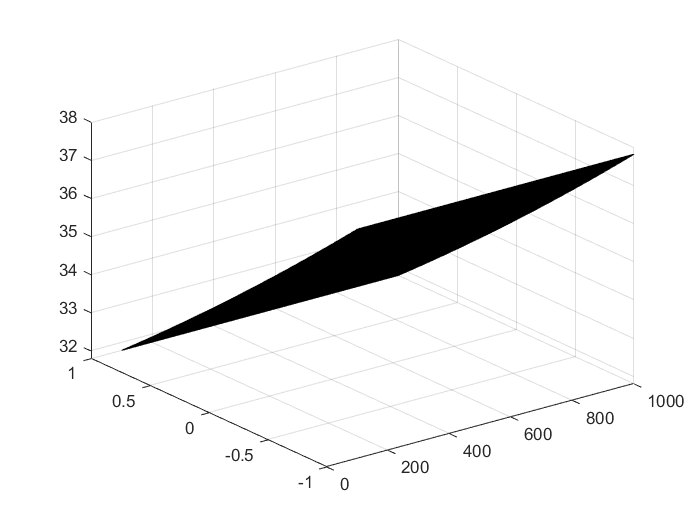

%PGFR = alpha \times e^W \times T^(Gamma)
%log(PGFR) = log(alpha) + W + Gamma log(T)
lpgfr_lme12 = fitlme(grdata,'log_PGFR ~ Weightcentered + sfc_centered');
lpgfr_lme22 = fitlme(grdata,'log_PGFR ~ Weightcentered + sfc_centered + (1|SubjectID)');
compare_complete1 = compare(lpgfr_lme12,lpgfr_lme22);
fe8 = fixedEffects(lpgfr_lme12);
Zt = exp(fe8(1) + fe8(3)*Ttp) + fe8(2)*Wtp;
figure(7)
surf(pweight,ptexture,Zt);